%f = @(x) sin(x*(1-x))
f = @(x) 1 + (1 + sin(x) - cos(x)).^2 - (sin(2*x) - cos(2*x) - 0.2).^2;
z = fzero(f, 2.3)

z = 4.2015


x = linspace(0,2*pi, 100);
y = f(x);
plot(x, y);
hold on
plot(x, linspace(0,0,100), 'r--');
z = bfindroot(f, 3, 9/2)

m = 4.1250

m = 4.3125

z = 4.3125

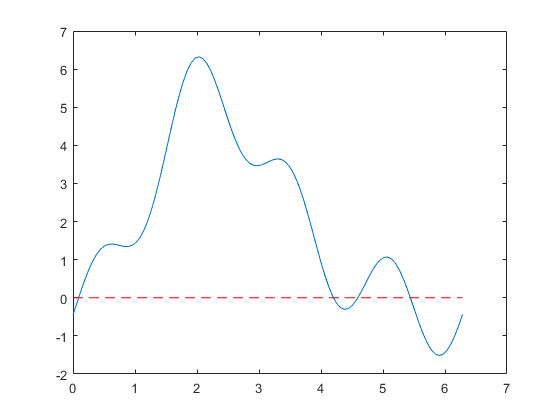

c = 4

c = 4

Error using ginput (line 84)
Interrupted by figure deletion


while true
    [x0, y0] = ginput(1);
    z = findroot(f, x0);
    plot(z, f(z), 'k *');
end

function root = bfindroot(f,a,b)
    i = 1;
    m = (a+b)/2;
    while f(m) > 10e-12
        i = i + 1;
        if i > 1000
            break
        end
        if f(m)*f(a) < 0
            m = (a + m)/2;
        end
        if f(m)*f(b) < 0
            m = (b + m)/2;
        end
    end
    root = m;
end

function root = findroot (f,a)
    i = 1;
    c = 0;
    xn = a;
    while abs(f(xn)) > 10e-12
        i = i + 1;
        if i > 1000
            break
        end
        xn = xn - f(xn)/((f(xn + 10e-12) - f(xn))/10e-12);
        c = c + 1;
    end
    c
    root = xn;
end 